# Creación de mascara para las imagenes, segmentación y recorte

Se describe el código usado que el usuario usará para definir la región de interes en el sistema de visión omnidireccional, debe definir el circulo de forma iterativa y al finalizar hacer doble clic para terminar de definir la mascara. Al final se muestra el resultado y los parametros de la máscara se guardan en una variable que se usa posteriormente. Luego loo que hacemos es aplicar la mascara creada en todas las imagenes de calibración y las gurdamos en un nuevo directorio para posteriormente usarlas en la calibración de la camara. A continuación el código para esta parte 

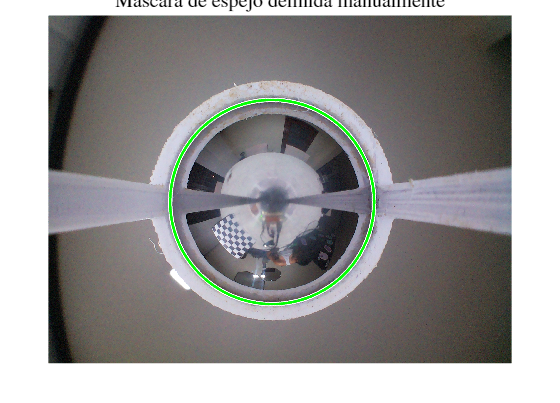

%% ------------------------------------------------------------
% 1) Dibujo manual de la máscara del espejo
% 2) Aplica la máscara y un recorte 1150×1150px 
%    a cada foto y guardado en carpeta de salida.
%% ------------------------------------------------------------

%% 1) Creación de la máscara sobre imagen de referencia
Iref = imread('fotos_cam/cal0.png');       % Imagen de referencia
figure; imshow(Iref);
title('Dibuja un circulo sobre el espejo y haz doble clic','Interpreter','latex');

% Dibuja y ajusta hasta cubrir el espejo
h = drawcircle('Color','r','LineWidth',2);
wait(h);  % espera al doble clic para finalizar

% Extrae centro y radio
pos = h.Center;   % [x y]
rad = h.Radius;   % radio en píxeles
delete(h);        % elimina el objeto interactivo
close;            % cierra la figura de referencia

% Construye máscara binaria circular
[H,W,~] = size(Iref);
[xg,yg] = meshgrid(1:W,1:H);
mask_ref = (xg - pos(1)).^2 + (yg - pos(2)).^2 <= rad.^2;

% Visualiza la máscara superpuesta para verificación
figure; imshow(Iref); hold on;
visboundaries(mask_ref,'Color','g','LineWidth',1.5);
title('Mascara de espejo definida manualmente','Interpreter','latex');

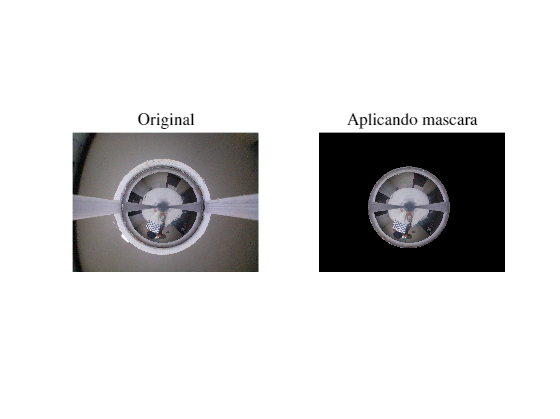

drawnow;

% Guarda la máscara y parámetros para reuso
save('espejo_mask.mat','mask_ref','pos','rad');

% Ejemplo de aplicación a otra imagen
I = imread('fotos_cam/cal1.png');    % otra foto distinta
Iseg = I;
for c = 1:3
    tmp = I(:,:,c);
    tmp(~mask_ref) = 0;
    Iseg(:,:,c) = tmp;
end

figure(); 
subplot(1,2,1), imshow(I),   title('Original','Interpreter','latex');
subplot(1,2,2), imshow(Iseg), title('Aplicando mascara','Interpreter','latex');


%% 2) Aplicación en ciclo de la máscara + recorte
% Carpetas de origen y destino
srcFolder = 'fotos_cam';            % origen de fotos
dstFolder = 'fotos_cam_segmentadas';% destino recortado y segmentado
if ~exist(dstFolder,'dir') % si no existe folder lo crea
    mkdir(dstFolder);
end

% Tamaño de recorte deseado
cropSize = 1150;

% Lista de archivos a procesar
imageFileNames = { ...
    fullfile(srcFolder,'cal0.png'),  fullfile(srcFolder,'cal1.png'),  ...
    fullfile(srcFolder,'cal2.png'),  fullfile(srcFolder,'cal3.png'),  ...
    fullfile(srcFolder,'cal4.png'),  fullfile(srcFolder,'cal5.png'),  ...
    fullfile(srcFolder,'cal6.png'),  fullfile(srcFolder,'cal7.png'),  ...
    fullfile(srcFolder,'cal8.png'),  fullfile(srcFolder,'cal9.png'),  ...
    fullfile(srcFolder,'cal10.png'), fullfile(srcFolder,'cal11.png'), ...
    fullfile(srcFolder,'cal12.png'), fullfile(srcFolder,'cal13.png'), ...
    fullfile(srcFolder,'cal14.png'), fullfile(srcFolder,'cal15.png'), ...
    fullfile(srcFolder,'cal16.png'), fullfile(srcFolder,'cal17.png'), ...
    fullfile(srcFolder,'cal18.png'), fullfile(srcFolder,'cal19.png')  ...
};

% Coordenadas de recorte centradas en pos
cx = pos(1);  cy = pos(2);
x1 = round(cx - cropSize/2);
y1 = round(cy - cropSize/2);

% Procesamiento de cada imagen
for k = 1:numel(imageFileNames)
    % Lee imagen original
    inPath = imageFileNames{k};
    I = imread(inPath);

    % Aplica máscara circular a cada canal RGB
    Iseg = zeros(size(I),'like',I);
    for c = 1:size(I,3)
        chan = I(:,:,c);
        chan(~mask_ref) = 0;
        Iseg(:,:,c) = chan;
    end

    % Ajusta límites para no salir del borde
    [hImg,wImg,~] = size(Iseg);
    x1c = max(1, min(wImg-cropSize+1, x1));
    y1c = max(1, min(hImg-cropSize+1, y1));

    % Recorta cuadrado 1150×1150
    rect = [x1c, y1c, cropSize-1, cropSize-1];
    Icrop = imcrop(Iseg, rect);

    % Construye ruta de salida y guarda
    [~, name, ext] = fileparts(inPath);
    outPath = fullfile(dstFolder, [name '_seg' ext]);
    imwrite(Icrop, outPath);
    fprintf('Guardada: %s\n', outPath);
end

Guardada: fotos_cam_segmentadas\cal0_seg.png
Guardada: fotos_cam_segmentadas\cal1_seg.png
Guardada: fotos_cam_segmentadas\cal2_seg.png
Guardada: fotos_cam_segmentadas\cal3_seg.png
Guardada: fotos_cam_segmentadas\cal4_seg.png
Guardada: fotos_cam_segmentadas\cal5_seg.png
Guardada: fotos_cam_segmentadas\cal6_seg.png
Guardada: fotos_cam_segmentadas\cal7_seg.png
Guardada: fotos_cam_segmentadas\cal8_seg.png
Guardada: fotos_cam_segmentadas\cal9_seg.png
Guardada: fotos_cam_segmentadas\cal10_seg.png
Guardada: fotos_cam_segmentadas\cal11_seg.png
Guardada: fotos_cam_segmentadas\cal12_seg.png
Guardada: fotos_cam_segmentadas\cal13_seg.png
Guardada: fotos_cam_segmentadas\cal14_seg.png
Guardada: fotos_cam_segmentadas\cal15_seg.png
Guardada: fotos_cam_segmentadas\cal16_seg.png
Guardada: fotos_cam_segmentadas\cal17_seg.png
Guardada: fotos_cam_segmentadas\cal18_seg.png
Guardada: fotos_cam_segmentadas\cal19_seg.png



% Guarda también parámetros de máscara y recorte
save(fullfile(dstFolder,'mask_params.mat'),'mask_ref','pos','rad','cropSize');

%% Fin del procesamiento
disp('Todas las imágenes han sido segmentadas y recortadas correctamente.');

Todas las imágenes han sido segmentadas y recortadas correctamente.
